# Problem 3

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
R_E = 6378.1363;
R_M = 1738.2;
mu_E = 398600.4415;
mu_M = 4902.8005821478;
a_M = 384400.00;

## Part a)

Hohmann Transfer Characterisitcs

rp_T_mag = 250 + R_E, ra_T_mag = a_M

rp_T_mag = 6.6281e+03

ra_T_mag = 384400

a_T = (rp_T_mag + ra_T_mag)/2

a_T = 1.9551e+05

e_T = 1 - rp_T_mag/a_T

e_T = 0.9661

v1_n_mag = sqrt(mu_E*(2/rp_T_mag - 1/a_T))

v1_n_mag = 10.8737

v1_n = [v1_n_mag 0]'

v1_n =    10.8737
         0


v2_0_mag = sqrt(mu_E*(2/ra_T_mag - 1/a_T))

v2_0_mag = 0.1875

v2_0 = [-v2_0_mag 0]'

v2_0 =    -0.1875
         0


energy = -mu_E/2/a_T

energy = -1.0194

n_T = sqrt(mu_E/a_T^3)

n_T = 7.3030e-06

period = 2*pi/n_T

period = 8.6036e+05

period_hr = period/3600

period_hr = 238.9877

period_day = period_hr/24

period_day = 9.9578

phase = pi - sqrt(mu_E/ra_T_mag^3)*period/2

phase = 2.0020

phase_deg = rad2deg(phase)

phase_deg = 114.7073

TOF = period/2

TOF = 4.3018e+05

TOF_day = period_day/2

TOF_day = 4.9789

Moon Orbit about Earth

v_M_mag = sqrt((mu_E)/a_M)

v_M_mag = 1.0183

v_M = [-v_M_mag, 0]'

v_M =    -1.0183
         0


Departure Parking Orbit

r1_mag = 250 + R_E

r1_mag = 6.6281e+03

v1_0_mag = sqrt(mu_E/r1_mag)

v1_0_mag = 7.7548

v1_0 = v1_0_mag * [1 0]'

v1_0 =     7.7548
         0



dv1 = v1_n-v1_0, dv1_mag = norm(dv1)

dv1 =     3.1188
         0


dv1_mag = 3.1188

Arrival Parking orbit

rp_M = 195 + R_M

rp_M = 1.9332e+03

Arrival Hyperbolic Orbit

v_inf_M = v2_0 - v_M

v_inf_M =     0.8308
         0


v_inf_M_mag = norm(v_inf_M)

v_inf_M_mag = 0.8308

v2_n_mag = sqrt(mu_M/rp_M)

v2_n_mag = 1.5925

dv2_mag = sqrt(v_inf_M_mag^2 + 2*mu_M/rp_M) - v2_n_mag

dv2_mag = 0.8080

Total

dvtotal_mag = dv1_mag + dv2_mag

dvtotal_mag = 3.9268

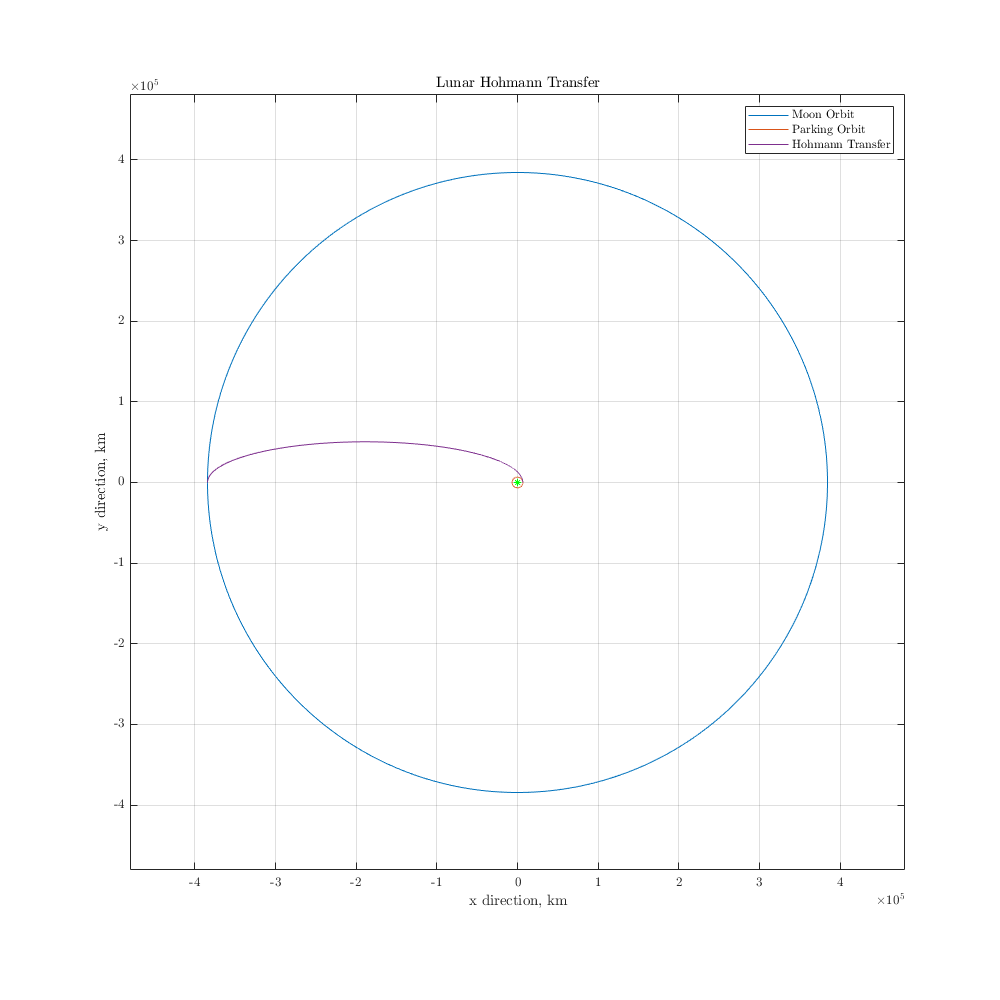


plotorbit(a_M,0,0,2*pi,0)
hold on
plotorbit(rp_T_mag,0,0,2*pi,0)
plot(0,0,'g*','MarkerSize',5)
plotorbit(a_T,e_T,0,pi,0)
maxlim = [-a_M a_M]*1.25;
xlim(maxlim), ylim(maxlim)
title('Lunar Hohmann Transfer')
xlabel('x direction, km')
ylabel('y direction, km')
legend('Moon Orbit','Parking Orbit','','Hohmann Transfer')
hold off
set(gcf,'position',[0,0,1000,1000])

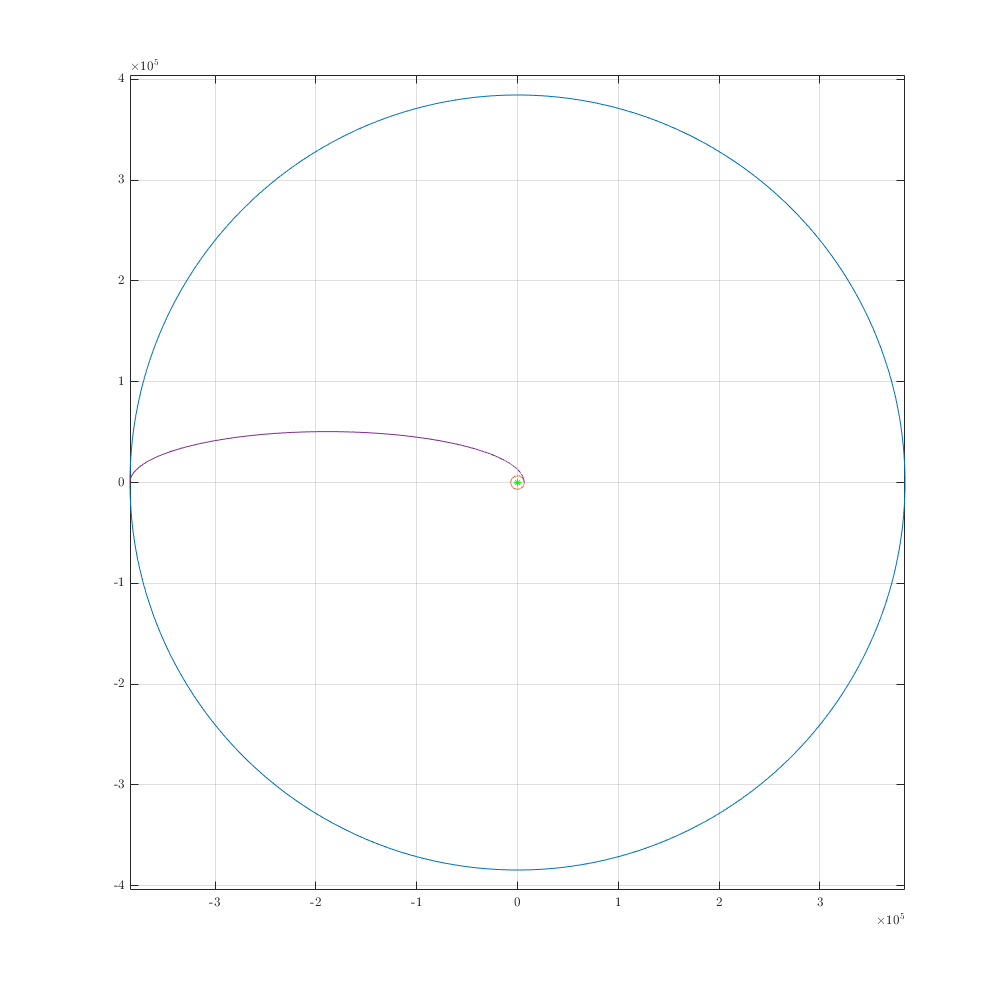


plotorbit(a_M,0,0,2*pi,0)
hold on
plotorbit(rp_T_mag,0,0,2*pi,0)
plot(0,0,'g*','MarkerSize',5)
plotorbit(a_T,e_T,0,pi,0)

dw = 0;

## Part b)

a_h = -mu_M/v_inf_M_mag^2

a_h = -7.1030e+03

e_h = 1 - rp_M/a_h

e_h = 1.2722


delta = 2*(asin(1/e_h)),delta_deg = rad2deg(delta)

delta = 1.8088

delta_deg = 103.6376

ths_inf = acos(-1/e_h), ths_inf_deg = rad2deg(ths_inf)

ths_inf = 2.4752

ths_inf_deg = 141.8188


v2_n_mag = sqrt(v_M_mag^2 + v_inf_M_mag^2 - 2*v_M_mag*v_inf_M_mag*cos(delta))

v2_n_mag = 1.4581


gamma_2_n = asin(v_inf_M_mag/v2_n_mag * sin(delta)), gamma_2_n_deg = rad2deg(gamma_2_n)

gamma_2_n = 0.5868

gamma_2_n_deg = 33.6223

v2_n_R = v2_n_mag*[sin(gamma_2_n);cos(gamma_2_n)]

v2_n_R =     0.8074
    1.2142


v_2_0_R = [0 v2_0_mag]'

v_2_0_R =          0
    0.1875


dveq = v2_n_R - v_2_0_R

dveq =     0.8074
    1.0267


norm(dveq)

ans = 1.3061

ths_2_n = atan((ra_T_mag * v2_n_mag^2 / mu_E)*sin(gamma_2_n)*cos(gamma_2_n)...
    /((ra_T_mag * v2_n_mag^2 / mu_E)*cos(gamma_2_n)^2-1))

ths_2_n = 1.1512

ths_2_n_deg = rad2deg(ths_2_n)

ths_2_n_deg = 65.9585


iCr2 = [cos(pi), -sin(pi); sin(pi) cos(pi)]

iCr2 =    -1.0000   -0.0000
    0.0000   -1.0000




a_post = -mu_E*(v2_n_mag^2 - 2*mu_E/ra_T_mag)^-1

a_post = -7.6283e+06

e_post = sqrt((ra_T_mag * v2_n_mag^2/mu_E -1)^2*cos(gamma_2_n)^2+sin(gamma_2_n)^2)

e_post = 1.0352

rp_post = a_post*(1-e_post)

rp_post = 2.6853e+05

energy_post = -mu_E/2/a_post

energy_post = 0.0261

dw = ths_2_n - pi

dw = -1.9904

dw_deg = rad2deg(dw)

dw_deg = -114.0415

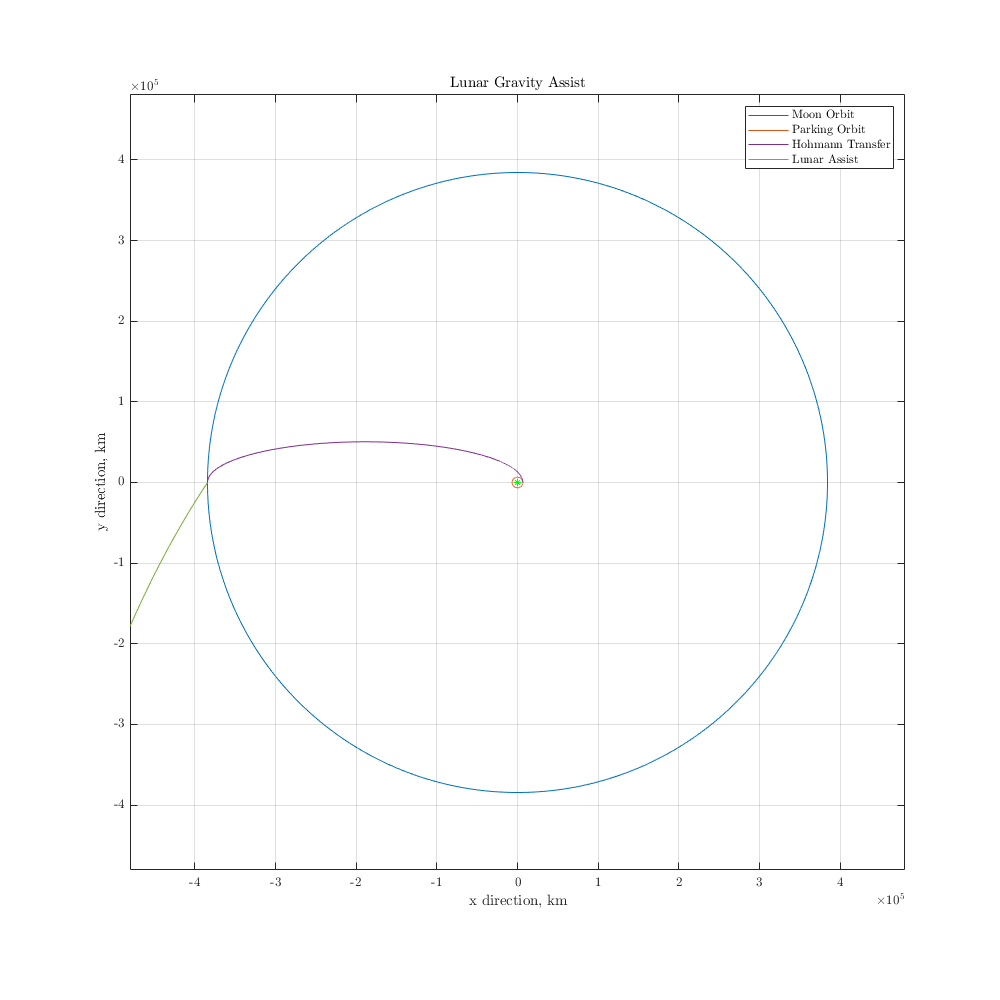




plotorbit(a_post,e_post,ths_2_n,acos(-1/e_post),dw)
title('Lunar Gravity Assist')
xlabel('x direction, km')
ylabel('y direction, km')
legend('Moon Orbit','Parking Orbit','','Hohmann Transfer','Lunar Assist')
maxlim = [-a_M a_M]*1.25;
xlim(maxlim), ylim(maxlim)
hold off

set(gcf,'position',[0,0,1000,1000])


### Function 1: Plot Orbit

function plotorbit(ai,ei,ths1,ths2,rotate)
ths_plot = linspace(ths1,ths2,2^12)';
ri = (ai*(1-ei^2))./(1+ei*cos(ths_plot));
ri = ri .* [cos(ths_plot-rotate),sin(ths_plot-rotate)];
plot(ri(:,1),ri(:,2))
grid on
axis equal
end

